# Atividade 10_04

Otávio Baziewicz Filho - 1942808

clc; clear; close all; 

## Top-hat para uniformizar a iluminação de fundo  

Segmentar os grãos de arroz da imagem rice.png da seguinte forma:

- Aplicar a transformada top-hat na imagem grayscale (a definição das operações morfológicas dilatação e erosão (das quais derivam a abertura e fechamento) e a definição do top-hat encontram-se nas notas de aula). IMPORTANTE: não pode usar a função imtophat. Use as funções imerode e imdilate. Observe (imshow) as saídas dos passos intermediários pra realmente entender o que está acontecendo.

- Aplicar uma limiarização global automática pelo método de Otsu (função graythresh). 

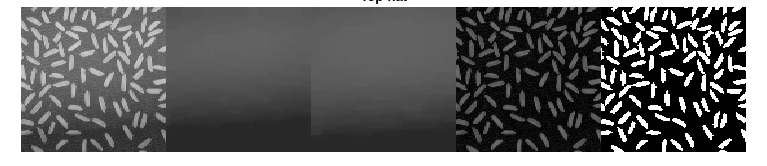

i = imread("rice.png");

se = strel("square", 30);
iErode = imerode(i, se);
iDilate = imdilate(iErode, se);
ith = i - iDilate;
bw = imbinarize(ith, graythresh(ith));

figure, montage({i, iErode, iDilate, ith, bw}, "Size", [1 5])
title("Top-hat")

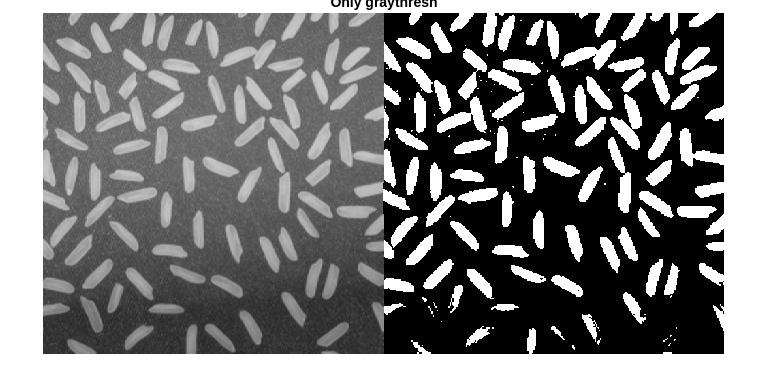


gtbw = imbinarize(i, graythresh(i));
figure, montage({i, gtbw}, "Size", [1 2])
title("Only graythresh")

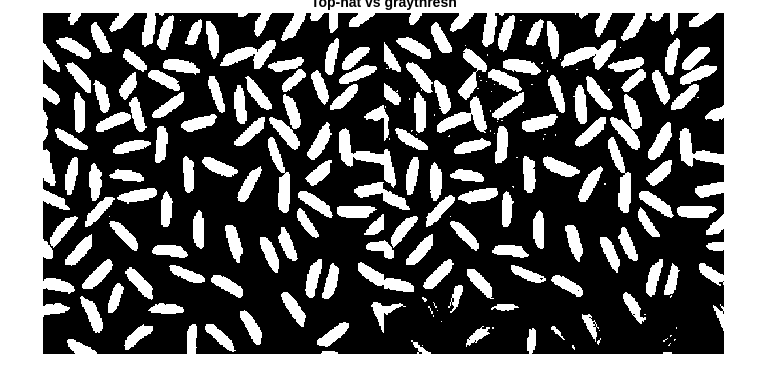


figure, montage({bw, gtbw}, "Size", [1 2])
title("Top-hat vs graythresh")